fs=512;  % Sample Rate
Avg=8;   % Sampling Average
fs_avg=fs/Avg;  %Averaged Sampling Rate 64 Hz


type='Maxem';
window=64*3/4;
Overlap_perc=90;
Butterworth=butterworth

Butterworth =          FilterStructure: 'Direct-Form II, Second-Order Sections'      
              Arithmetic: 'double'                                     
               sosMatrix: [1 0 -1 1 -1.6917043661597 0.711648515536758]
             ScaleValues: [0.144175742231621;1]                        
     OptimizeScaleValues: true                                         
        PersistentMemory: false                                        
                                                                       

cd 'C:\Users\Mohammad Afaq\OneDrive\Documents\LUMS-Shared\ShareAbleSprojFolder\sproj research\Work\PPG signal Processing\RemovingMotionArtifacts\FrameWork'



Test_data=xlsread("testing.xlsx"); 
type='Maxem';


if strcmp(type,'Maxem')
    %Using Green LED signal
    PPG_data=(Test_data(:,3));
    PPG_data_ref_g2=(Test_data(:,4));
    [perf_data, PPG_data] = pre_process(Butterworth,PPG_data,fs_avg); %seperating perfusion and PPG waveform 
    [perf_data_g2, PPG_data_g2] = pre_process(Butterworth,PPG_data_ref_g2,fs_avg); %seperating perfusion and PPG waveform 
    ACC_x=(Test_data(:,7));
    ACC_y=(Test_data(:,8));
    ACC_z=(Test_data(:,9));
elseif strcmp(type,'Empatica')
    PPG_data=Test_data(15*fs_avg:length(Test_data)-1*fs_avg);
    [perf_data, PPG_data] = pre_process(Butterworth,PPG_data,fs_avg);
end



window=[50 57]

window =     45    57


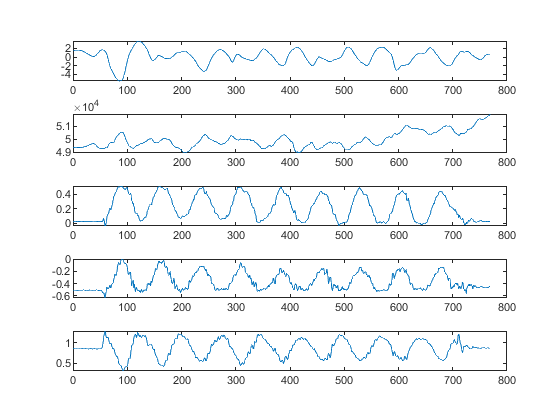


figure
subplot(5,1,1)
plot(PPG_data(window(1)*64:window(2)*64,1))
subplot(5,1,2)
plot(PPG_data_ref_g2(window(1)*64:window(2)*64,1))
subplot(5,1,3)
plot(ACC_x(window(1)*64:window(2)*64,1))
subplot(5,1,4)
plot(ACC_y(window(1)*64:window(2)*64,1))
subplot(5,1,5)
plot(ACC_z(window(1)*64:window(2)*64,1))

synthetic_Data= Averaging_window(PPG_data,window);

positive


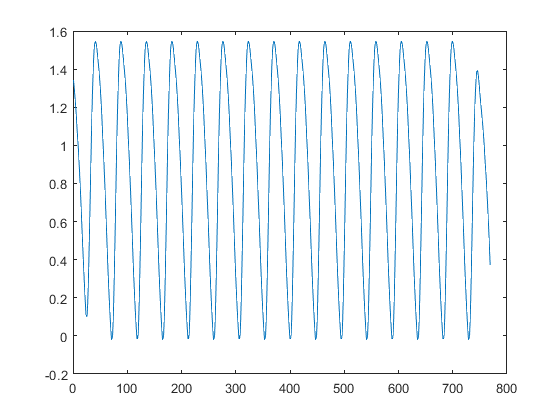

data=PPG_data(window(1)*64:window(2)*64,1);
ref_data= PPG_data_ref_g2(window(1)*64:window(2)*64,1);
figure
plot(synthetic_Data)

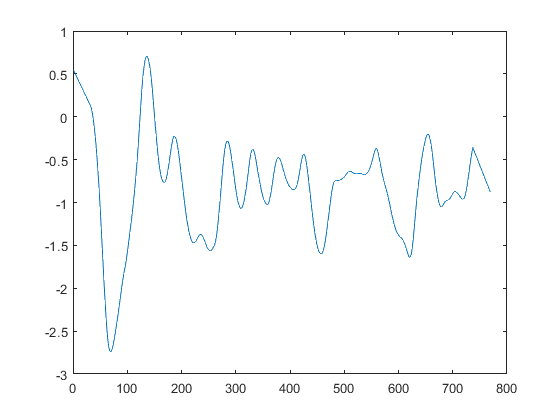


noise=data-synthetic_Data;
figure
plot(sgolayfilt(noise,1,65))

temp=AdaptiveFilter(synthetic_Data,data,1,0.01,32,0.99,0.01);
TEMP=sgolayfilt(temp,3,129)

TEMP =     1.0744
    1.0339
    0.9952
    0.9583
    0.9231
    0.8896
    0.8578
    0.8276
    0.7990
    0.7720


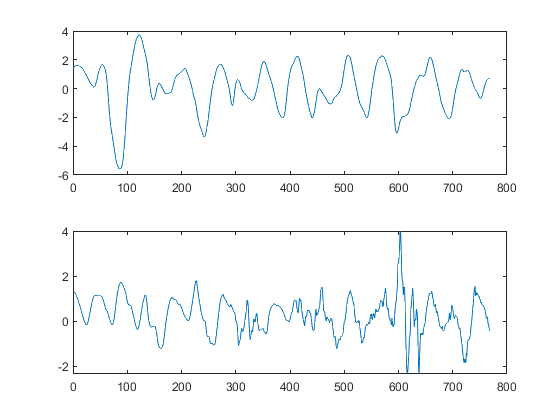

[HRF] = HeartRate(PPG_data((10-5)*64:10*64));
%%[temp] = NotchFilter(temp,HRF,64);

figure
subplot(2,1,1)
plot(PPG_data(window(1)*64:window(2)*64,1))
subplot(2,1,2)
plot(temp)

function [PPG_Data] = AdaptiveFilter(PPG_sig,Ref_sig,ref_type,mu,len,forf,inic)
    d1 = PPG_sig;
    d2 = Ref_sig;
    

    if ref_type == 1
        ref = d1-d2;
        ref=sgolayfilt(ref,1,129);
        
        mu = mu;
        rls1 = dsp.RLSFilter(len,'Method','Sliding-window RLS','ForgettingFactor',forf,'InitialInverseCovariance',inic);
        [x1,~] = rls1(d1,ref);
        [x2,~] = rls1(d2,ref);
    
        [Ta] = fundamental_period_extraction(x1);
        [new_ref_sig1,new_ref_sig2] = B_optim(x1,x2,ref,Ta,mu);
        %lms = dsp.LMSFilter(32,'Method','Normalized LMS','StepSize',mu);
        rls2 = dsp.RLSFilter(len,'Method','Sliding-window RLS','ForgettingFactor',forf,'InitialInverseCovariance',inic);
        [ppg_red,~] = rls2(new_ref_sig2,x1);
        %[ppg_IR,~] = rls2(new_ref_sig2,x2);
    else
        ref = d2;

        rls1 = dsp.RLSFilter(32,'Method','Sliding-window RLS','ForgettingFactor',0.999,'InitialInverseCovariance',0.1);
        [x1,~] = rls1(d1,ref);
        [x2,~] = rls1(d2,ref);
        rls2 = dsp.RLSFilter(32,'Method','Sliding-window RLS','ForgettingFactor',0.999,'InitialInverseCovariance',0.1);
        [ppg_red,~] = rls2(d1-x1,x1);
    end


    PPG_Data = d1 - ppg_red; %(ppg_IR/max(ppg_IR));
end


function [new_ref_sig1,new_ref_sig2] = B_optim(x1,x2,ref_sig,Ta,mu)
    %B_OPTIM Summary of this function goes here
    %   Detailed explanation goes here
    %lms = dsp.LMSFilter(640,'Method','mmse','StepSize',mu)
    %[ppg_red,error] = lms(new_ref_sig2,x1);
    
    rv = mean(x2./ref_sig);
    s_as = x1 - rv*x2;%dot(rv,transpose(x2));
    
    lms = dsp.LMSFilter('Length',64,'Method','LMS','StepSize',mu);
    [est_Sas] = lms(x1,s_as);
%    [mse,meanw,w,tracek] = msesim(lms,s_as,x1);
 %   est_Sas = filter([0 -w(2:end)],1,x2);
    est_Sas2 = x1 - est_Sas;
    filter_coeff = lpc(est_Sas2,Ta);
    
    a = (mean(x1.*x1,'all')-rv*mean(x1.*x2,'all'))/mean(s_as,'all');
    b = (a*rv)/(1-a);
%     if b > 20
%         b = 0.1;
%     end
    x3 =[];
    for i=1:length(x2)
        if x2(i)>x1(i)
            x3(i) = 0.95*x2(i);
        elseif x2(i)<x1(i)
            x3(i) = 1.05*x2(i);
        else
            x3(i) = x2(i);
        end
    end
        b = 1.05;
    %e1 = x1 - a.*s_as;
    
    
    new_ref_sig1 =  est_Sas2;
    new_ref_sig2 = x1 - x3'; 
    
end


function [Ta] = fundamental_period_extraction(x1)
    x = xcorr(x1);
    l = length(x);
    t_max = floor(l/3);
    t = 1:t_max;
    y = zeros(l,1);
    z = [];
    for i = 1:t_max
        y(i) = 1;
        y(2*i) = 0.9;
        y(3*i) = 0.8;
        z1 = y.*x;
        Z = fft(z1);
        pow = Z.*conj(Z);
        pow_acc = sum(Z);
        z = [z pow_acc];
    end
    [~,ind] = max(z);
    Ta = ind;
end



function [PPG_sig_proc] = NotchFilter(PPG_sig,HRF,fs)
    
%     notchspec = fdesign.notch('N,F0,BW',6,HRF,0.1,fs);
%     notchfilt = design(notchspec,'SystemObject',true);
%     %fvt= fvtool(notchfilt, 'Color','white');
%     notchspec1 = fdesign.notch('N,F0,BW',6,2*HRF,0.1,fs);
%     notchfilt1 = design(notchspec1,'SystemObject',true);
    w0 = HRF/(fs/2);
    bw = w0/45;
    [b,a] = iirnotch(w0,bw);
    
    w1 = (HRF*2)/(fs/2);
    bw1 = w1/90;
    [b1,a1] = iirnotch(w1,bw1);
    
    proc_sig = filter(b,a,PPG_sig);
    proc_sig1 = filter(b1,a1,PPG_sig);
    
    noise = PPG_sig - proc_sig - proc_sig1;
    PPG_sig_proc = PPG_sig - noise;
    PPG_sig_proc = normalize(PPG_sig_proc);
end

function [HRF] = HeartRate(PPG_sig)
    [~,loc] = findpeaks(PPG_sig,64,'MinPeakDistance',0.7);
    peak_diff = [];
    for i=1:length(loc)-1
        peak_diff(i) = loc(i+1) - loc(i); 
    end
    HRF = mean(peak_diff);
end


function [replace] = Averaging_window(PPG,windows)

    if (windows(1)-5)>0
        data=PPG((windows(1)-5)*64:(windows(1)-1)*64);
        %plot(data)
    else
        display("need more data to calibrate")
        return
    end
    
    double_der=diff(diff(data));

    [peaks,locs]=findpeaks(double_der,'MinPeakHeight',0.02,"MinPeakDistance",32);
    
    distances=[];
    
    for i=1:length(locs)-1
        distances=[distances abs(locs(i)-locs(i+1))];
    end
    
    len=min(distances);
    
    PPG_sum=[];
    for i=1:length(locs)-1
        PPG_sum=[PPG_sum data(locs(i):locs(i)+len)];
    end
    
    sum=zeros(len+1,1);
    for i=1:length(distances)
        sum=sum+PPG_sum(:,i);
    end
    
    Averaged=sum/length(distances);
    %plot(PPG_sum)
    %plot(Averaged)
    
    
    window=windows(2)-windows(1);
    samples=window*64;
    d=length(Averaged);
    bias=Averaged(length(Averaged))-Averaged(1);
    
    
    second_sample=PPG(windows(1)*64+1);
    first_sample=PPG(windows(1)*64);
    last_sample=PPG((windows(1)*64)-1);
    %grad=''
    initial_index=0;
    
    if second_sample>first_sample 
        if first_sample>last_sample
            %grad='positive'
            display('positive')
            for i=2:length(Averaged)-1
                gradi=Averaged(i+1)-Averaged(i-1);
                if gradi>0
                    if Averaged(i)<second_sample && Averaged(i)>first_sample
                        initial_index=i;
                    end
                end
            end
        end
    end
    
    if second_sample<first_sample 
        if first_sample<last_sample
            %grad='negative'
            display('negative')
            for i=2:length(Averaged)-1
                gradi=Averaged(i+1)-Averaged(i-1);
                if gradi<0
                    if Averaged(i)>second_sample && Averaged(i)<first_sample
                        initial_index=i;
                    end
                end
            end
        end
    end
    
    if initial_index==0
        initial_index=round(length(Averaged)/2);
    end
    %display(initial_index)
    replace=[Averaged(initial_index:length(Averaged))];
    used=length(Averaged)-initial_index;
    %plot(replace)
    
    choice=[];
    i=1;
    while(used<samples)
        if (samples-used)<d
            choice=Averaged(1:samples-used);
        else
            choice=Averaged;
        end
        choice=choice+i*bias;
        replace=[replace;choice];
        used=used+length(choice);
        i=i+1;
    end
    
    trend=sgolayfilt(replace,1,1*64+1);
    %plot(replace)
    %figure
    %plot(replace-trend)
    replace=replace-trend;
    
    shift=replace(1)-last_sample;
    replace=replace-shift;
    %plot(temp)
    %plot(PPG)
end

function [PPG,Ref] = SGolay_Filter(PPG_sig,Ref_sig,order,wind_len)
    PPG = sgolayfilt(PPG_sig,order,wind_len);
    Ref = sgolayfilt(Ref_sig,order,wind_len);
end

function [perf, PPG] = pre_process(fil,data,fs)
    perf=sgolayfilt(data,2,4*fs +1);
    PPG=data-perf;
    PPG=-1*PPG;
    PPG=filter(fil,PPG);
    PPG=normalize(PPG);
    
end

function Hd = butterworth
    %BUTTERWORTH Returns a discrete-time filter object.
    
    % MATLAB Code
    % Generated by MATLAB(R) 9.9 and Signal Processing Toolbox 8.5.
    % Generated on: 02-Apr-2021 15:37:40
    
    % Butterworth Bandpass filter designed using FDESIGN.BANDPASS.
    
    % All frequency values are in Hz.
    Fs = 64;  % Sampling Frequency
    
    N   = 2;    % Order
    Fc1 = 0.6;  % First Cutoff Frequency
    Fc2 = 4;    % Second Cutoff Frequency
    
    % Construct an FDESIGN object and call its BUTTER method.
    h  = fdesign.bandpass('N,F3dB1,F3dB2', N, Fc1, Fc2, Fs);
    Hd = design(h, 'butter');
end